We again look at finding a solution of $xe^x=2$ near $x=1$. To apply Newton's method, we need to calculate values of both the residual function $f$ and its derivative. 

f = @(x) x.*exp(x) - 2;
dfdx = @(x) exp(x).*(x+1);

We don't know the exact root, so we use the built-in `fzero` to determine the ``true'' value.

format long,  r = fzero(f,1)

r =    0.852605502013726


We use $x_1=1$ as a starting guess and apply the iteration in a loop, storing the sequence of iterates in a vector.

x = 1;
for k = 1:6
    x(k+1) = x(k) - f(x(k)) / dfdx(x(k));
end

Here is the sequence of errors (leaving out the last value, now serving as our exact root). 

format short e
err = x' - r

err =    1.4739e-01
   1.5274e-02
   1.7787e-04
   2.4355e-08
   4.4409e-16
  -1.1102e-16
  -1.1102e-16


Glancing at the exponents of the errors, they roughly form a neat doubling sequence until the error is comparable to machine precision. We can see this more precisely by taking logs.

format short
logerr = log(abs(err))

logerr =    -1.9146
   -4.1816
   -8.6344
  -17.5305
  -35.3505
  -36.7368
  -36.7368


Quadratic convergence isn't as graphically distinctive as linear convergence.

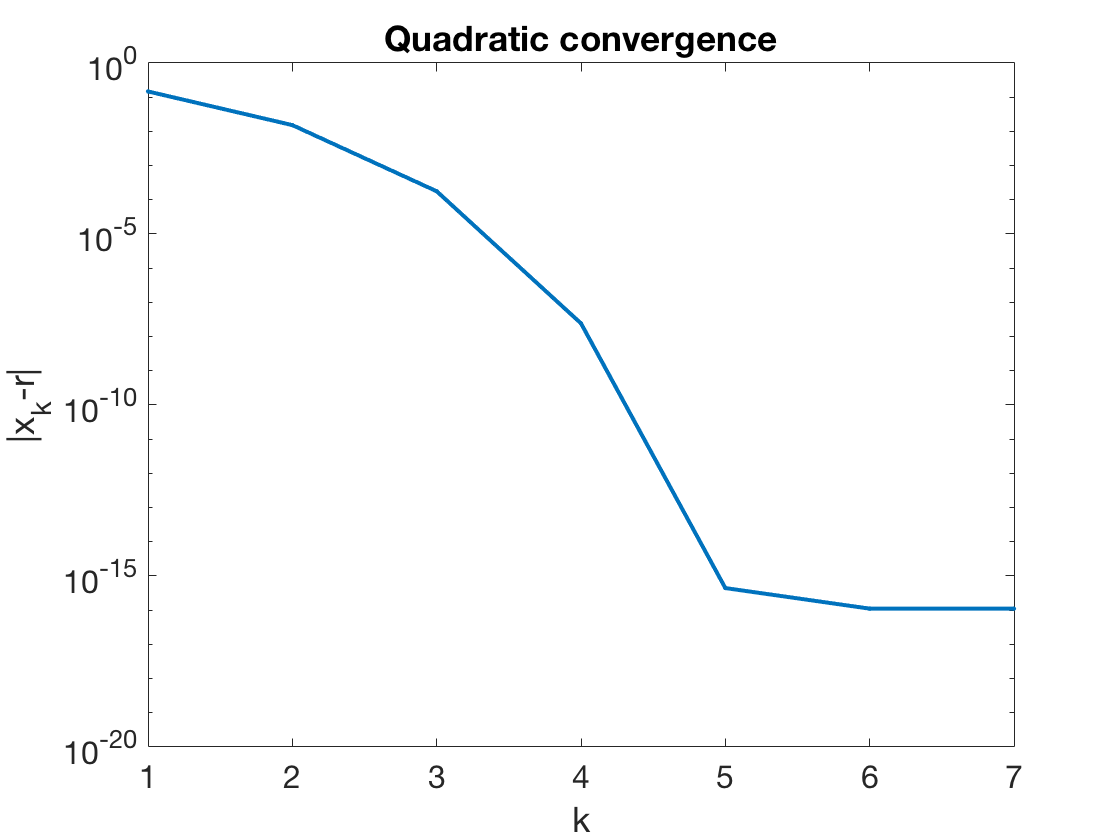

semilogy(abs(err),'.-')
xlabel('k'), ylabel('|x_k-r|')    % ignore this line
title('Quadratic convergence')    % ignore this line

This looks faster than linear convergence, but it's not easy to say more. If we could use infinite precision, the curve would continue to steepen forever.